# Let's get familiar with **Transfer Functions** and **Frequency Response Functions** (FRFs)

`Bradley Horton: bhorton@mathworks.com`

## Define a Linear Dynamic system

Clear your workspace

clear

Let's explore the familiar 2nd order system


$$H\left(s\right)\;\;=\;\;\frac{1}{s^2 \;\;+\;\;\;2\ldotp \zeta \ldotp \omega_n \ldotp s\;\;\;+\;\;\;\omega_n^2 }$$


This transfer function has POLES at:

- 
$$\lambda \;\;=\;\;-\zeta \ldotp {\omega_n \;\;+\;\;j\ldotp \omega_n \ldotp \sqrt{1-\zeta^2 }}_{\;}$$


- 
$$\bar{\lambda} \;\;=\;\;-\zeta \ldotp {\omega_n \;\;-\;\;j\ldotp \omega_n \ldotp \sqrt{1-\zeta^2 }}_{\;}$$


dr = 0.1;
wn = 5;
fn = wn/(2*pi);

THE_POLES = [(-dr*wn + 1i*wn*sqrt(1 - dr^2));
             (-dr*wn - 1i*wn*sqrt(1 - dr^2)) ]

THE_POLES =   -0.5000 + 4.9749i
  -0.5000 - 4.9749i


Define a Transfer Function to play with

- Define a formula version

- Define a TF object version (Control Systems toolbox)

H        = @(s)  1 ./ (s.^2  +  2*dr*wn*s + wn^2)

H = function_handle with value:
    @(s)1./(s.^2+2*dr*wn*s+wn^2)



H_tf_obj = tf(  [1], [1, (2*dr*wn), (wn^2)]     )


H_tf_obj =
 
       1
  ------------
  s^2 + s + 25
 
Continuous-time transfer function.


## Plot the FRF

Recall that the **Frequency Response Function** (FRF) is just the Transfer function evaluated along the imaginary axis, i.e.:

- 
$$\mathrm{FRF}\left(\omega \right)\;\;=\;\;H\left(s=j\ldotp \omega \right)$$


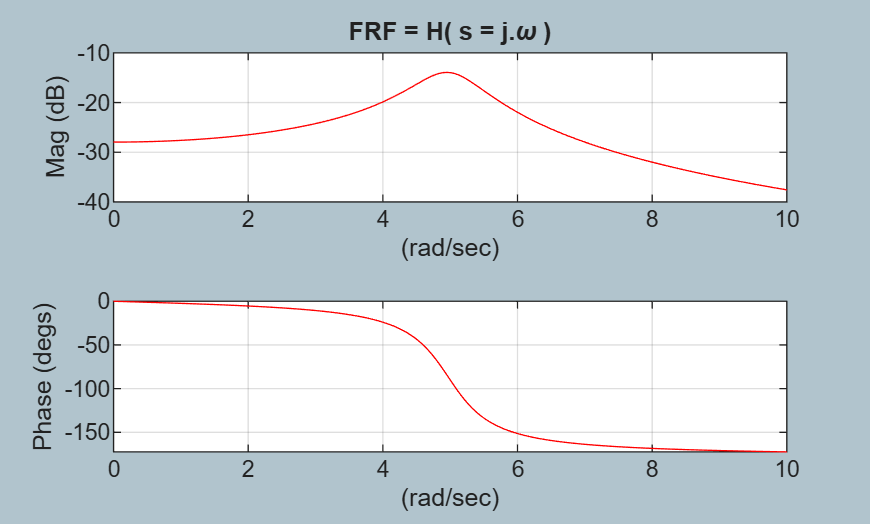

w_list  = 0:0.01:10;  % (rad/sec)

the_FRF = H(1i*w_list);

figure;
    hax(1) = subplot(2,1,1);
        plot(w_list, 20*log10( abs(the_FRF) ), "-r");
                    grid on;  axis tight
                    xlabel("(rad/sec)"); ylabel("Mag (dB)");  
                    title("FRF = H( s = j.\omega )");
                    ylim([-40, -10])
    hax(2) = subplot(2,1,2);
        plot(w_list, rad2deg( angle(the_FRF) ), "-r");
                    grid on;  axis tight
                    xlabel("(rad/sec)"); ylabel("Phase (degs)");  

## Plot the Transfer Function

Recall that the [**Laplace transform**](https://en.wikipedia.org/wiki/Laplace_transform) $s$ variable has the form

- 
$$s\;\;=\;\;\sigma \;\;+\;\;j\ldotp \omega$$


sigma_list         = -1:0.01:1;

Create a grid of $\sigma$ and $\omega$ so that we can plot a surface

[W_MAT, SIGMA_MAT] = meshgrid(w_list,  sigma_list);
S_MAT              = SIGMA_MAT + 1i*W_MAT;

Evaluate our Transfer function at every grid point

TF_MAT             = H(S_MAT);

whos *_MAT

  Name             Size                Bytes  Class     Attributes

  SIGMA_MAT      201x1001            1609608  double              
  S_MAT          201x1001            3219216  double    complex   
  TF_MAT         201x1001            3219216  double    complex   
  W_MAT          201x1001            1609608  double              



Recall the POLES of the transfer function

THE_POLES

THE_POLES =   -0.5000 + 4.9749i
  -0.5000 - 4.9749i


Plot the Transfer Function surface    

- you should be able to see the singularity at the pole $\lambda \;\;=\;\;-\zeta \ldotp {\omega_n \;\;+\;\;j\ldotp \omega_n \ldotp \sqrt{1-\zeta^2 }}_{\;}$

figure;
  surf(W_MAT, SIGMA_MAT, 20*log10( abs(TF_MAT) ), "EdgeColor","none");
        xlabel("w (rad/sec) = IMAG(s)"); 
        ylabel("sigma = REAL(s) "); 
        zlabel("(dB)");
        hax      = gca;
        hax.YDir = "reverse";
  hold on
        plot3(w_list, zeros(size(w_list)), 20*log10(abs(the_FRF)), '-r', ...
               "LineWidth",3)
        title("Transfer Function surface AND"+newline+...
             "FRF in red")

And look at it again but looking at the IMAGINARY axis

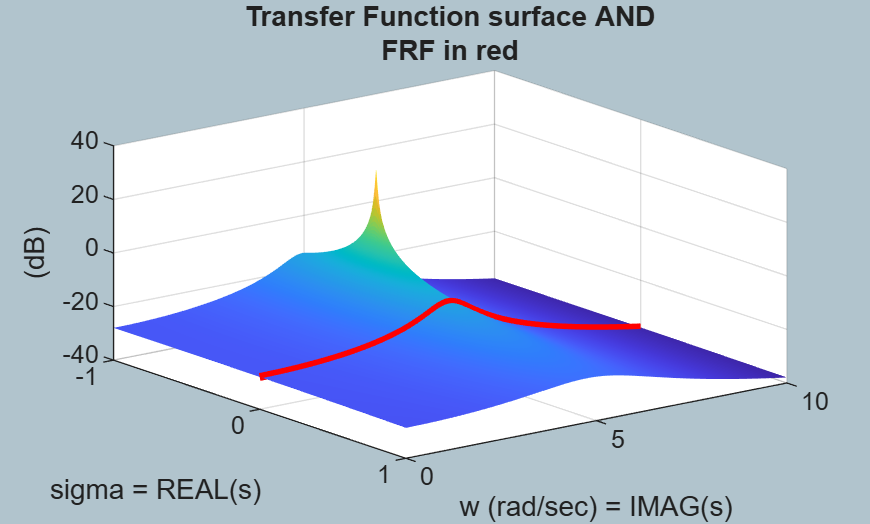

hf = figure;
   copyobj(hax, hf);

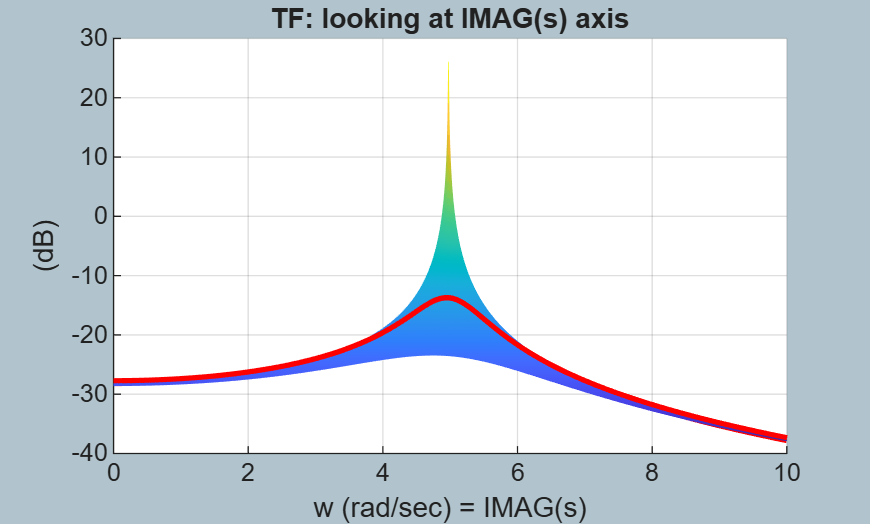

        view([0,0]);
        title("TF: looking at IMAG(s) axis")

And look at it again but looking at the REAL axis

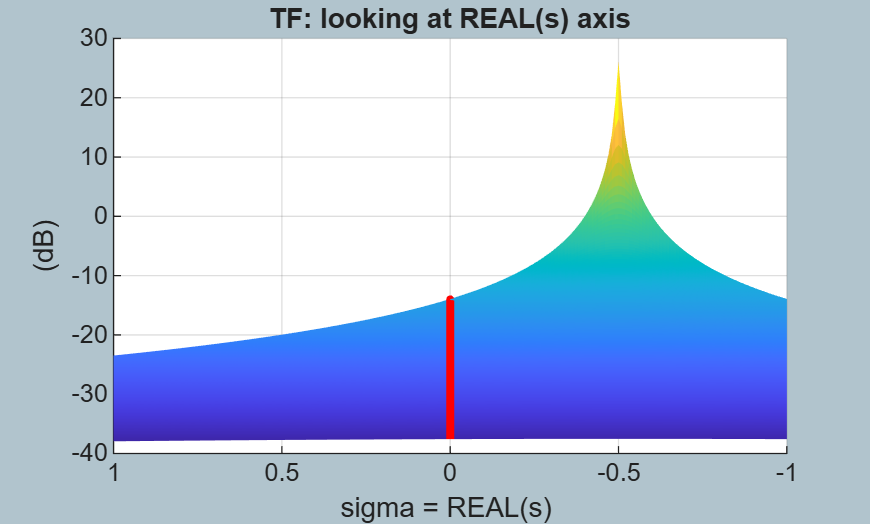

hf = figure;
   copyobj(hax, hf);
        view([90,0])
        title("TF: looking at REAL(s) axis")

## The FRF - Control Systems Toolbox

You're probably familiar with defining Linear systems using the **Control Systems Toolbox** - e.g.:  `tf(), bode(), bodeplot()`, etc.  The [`bodeplot()`](https://au.mathworks.com/help/releases/R2024b/control/ref/controllib.chart.bodeplot.html) function simply plots the FRF of the Transfer Function

my_bode_plot_opts           = bodeoptions;
my_bode_plot_opts.FreqScale = "Linear";

The following plot should be identical to the FRF plot that we made earlier in this script

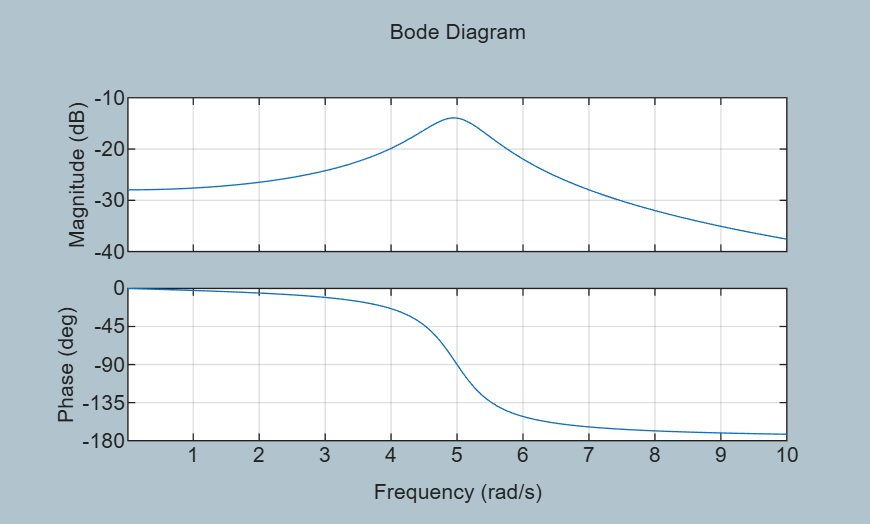

figure;
    bodeplot( H_tf_obj, w_list, my_bode_plot_opts);
        grid on

## While we're playing with a 1-dof system

While we're here, let's look at the RESIDUE fitting algorithm

w_list  = 1:0.1:10;  % (rad/sec)
f_list  = w_list/(2*pi);
the_FRF = H(1i*w_list);

[my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( fn, ...
                                                    dr, ...
                                                    f_list, ...
                                                    the_FRF    )      

my_R = 0.0000 - 0.1005i

my_e = 7.9195e-19 + 4.8584e-18i

my_f = 5.4586e-18 + 9.2343e-18i

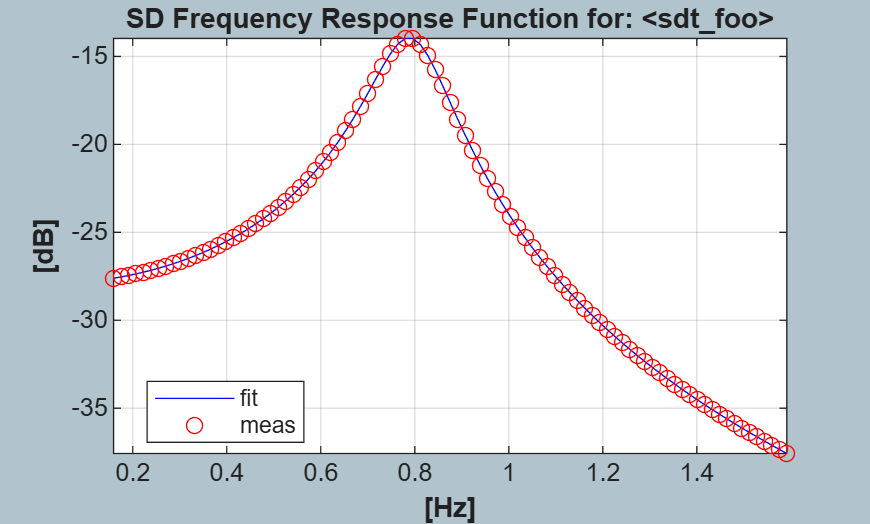


my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf( dr,         ...
                                     2*pi*fn, ...
                                     my_R, my_e, my_f);

my_sdyn_OBJ.s_w_fhz_col = f_list;

figure
    my_sdyn_OBJ.plot_db
hold on
    plot(f_list, 20*log10(abs(the_FRF)), "ro");
    legend(["fit","meas"], Location="best")

And there is a relationship between the first order RESIDUE and the numerator of the Second Order Section.  According to [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation) , we have:

- 
$$H\left(s\right)\;=\;\frac{1}{m\ldotp s^2 \;\;+\;c\ldotp s\;\;+\;k}\;\;\;=\;\;\;\;\frac{\frac{1}{m}}{s^2 \;\;\;+\;\;\;2\ldotp \zeta \ldotp \omega_n \ldotp s\;\;\;\;+\;\;\;\omega_n^2 }\;\;=\;\;\frac{-\;2\ldotp B\ldotp \omega_n \ldotp \sqrt{1-\zeta^2 }}{s^2 \;\;\;+\;\;\;2\ldotp \zeta \ldotp \omega_n \ldotp s\;\;\;\;+\;\;\;\omega_n^2 }$$


- 
$$H\left(s\right)\;\;\;\;=\;\;\frac{R}{s-\lambda }\;\;\;+\;\;\;\frac{\bar{R} }{s-\bar{\lambda} }\;\;\;=\;\;\;\frac{i\ldotp B}{s-\lambda }\;\;\;+\;\;\;\frac{-i\ldotp B}{s-\bar{\lambda} }$$


And in our case we have:

my_B        = imag(my_R);
my_1_over_m = -2*my_B*wn*sqrt(1 - dr^2)

my_1_over_m = 1